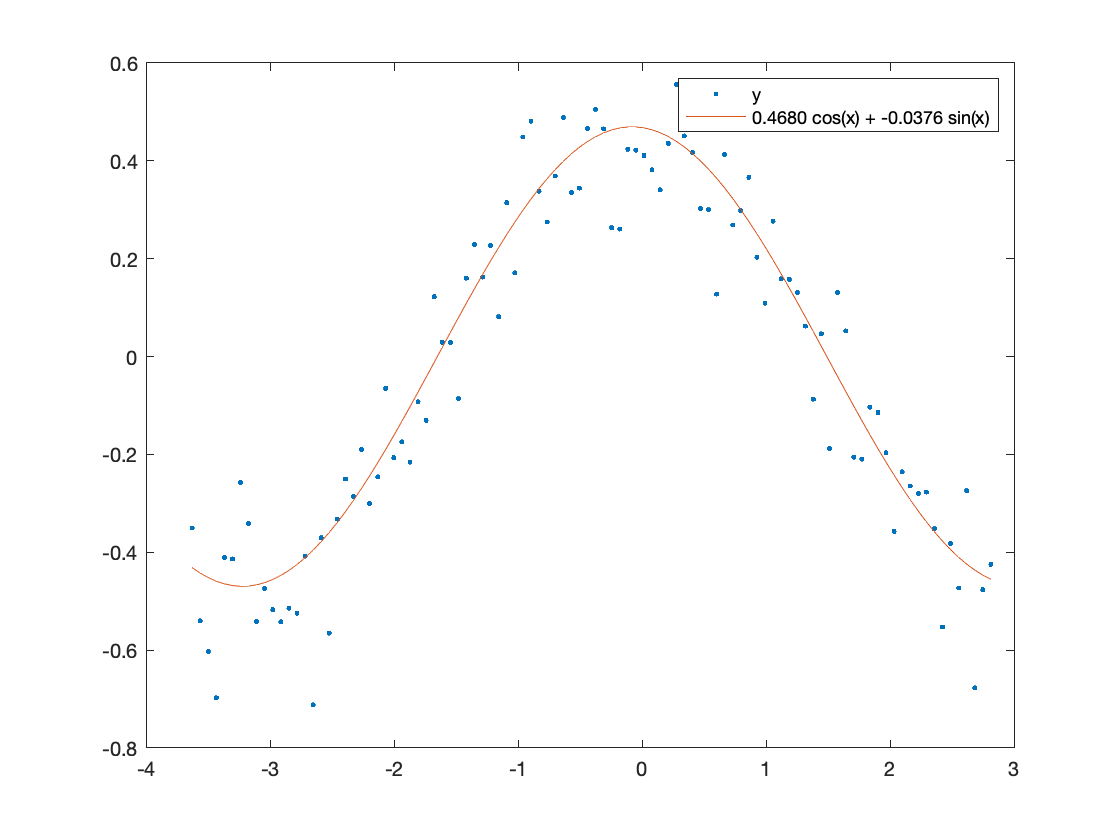

clear; clc; close all;

% Dataset given
x = linspace(-rand(1),rand(1)).'*10;
y = randn(1)*cos(x)+randn(1)*sin(x)+randn(size(x))*0.1;

% Build your system matrix here
A = [cos(x) sin(x)];

% Solve the system, and then unpack the individual values into a and b
c = A \ y;
a = c(1);
b = c(2);

yf = a .* cos(x) + b .* sin(x); % calculate your fitted y here using c

plot(x, y, '.', x, yf, '-'); % overlay plot for testing
legend('y', sprintf('%0.4f cos(x) + %0.4f sin(x)', a, b));